clear;
clc;

%heart attack
gender = [0,0];                 %Assign gender with empty array, male=1, 
chest_pain_type = [0,0,0,0];    %female=0 for person with heart disease
fbs = [0,0];
ecg = [0,0,0];
exang = [0,0];
slope = [0,0,0];                %Assign number of variables with empty array  
ca = [0,0,0,0];                 %with corresponsing attributes for person with
thal = [0,0,0];                 %heart disease

%healthy
gender_h = [0,0];                   %Assign gender with 2 variable, male=1, 
chest_pain_type_h = [0,0,0,0];      %female=0 for healthy person
fbs_h = [0,0];
ecg_h = [0,0,0];
exang_h = [0,0];                    %Assign number of variables with empty array 
slope_h = [0,0,0];                  %with corresponding attributes for healthy person
ca_h = [0,0,0,0];
thal_h = [0,0,0];

[heart_attack,healthy,T]=positive();    %for person positive for heart disease

chest_pain_type =fourvariable(heart_attack,chest_pain_type,3,1,2,3,4);   %for person with heart disease, chest pain type with 
fbs = twovaraible(heart_attack,fbs,6,1,0);                               %user defined function four variable cases with 
ecg= threevaraible(heart_attack,ecg,7,0,1,2);                            %corresponding attributes
exang = twovaraible(heart_attack,exang,9,1,0);
slope =  threevaraible(heart_attack,slope,11,1,2,3);
ca=fourvariable(heart_attack,ca,12,0,1,2,3);
thal= threevaraible(heart_attack,thal,13,3,6,7);
gender = twovaraible(heart_attack,gender,2,1,0);

chest_pain_type_h=fourvariable(healthy,chest_pain_type_h,3,1,2,3,4); %for healthy person, chest pain type with user defined function 
fbs_h = twovaraible(healthy,fbs_h,6,1,0);                            %four variable cases with corresponding attributes
ecg_h=threevaraible(healthy,ecg_h,7,0,1,2);
exang_h = twovaraible(healthy,exang_h,9,1,0);
slope_h =  threevaraible(healthy,slope_h,11,1,2,3);
ca_h=fourvariable(healthy,ca_h,12,0,1,2,3);
thal_h=threevaraible(healthy,thal_h,13,3,6,7);
gender_h = twovaraible(healthy,gender_h,2,1,0);

[avg,sdv] = calculationstdev_mean(heart_attack(:,1)); %calculation of average and standard deviation of those with heart disease
[avg_h,sdv_h] = calculationstdev_mean(healthy(:,1)); %calculation of average and standard deviation of those that are healthy

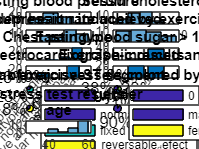

figure(1) %Plots of attributes contributing to ones with heart disease
plotting(heart_attack,chest_pain_type,fbs,ecg,exang,slope,ca,thal,gender);

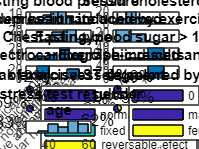


figure(2) %Plots of attributes contributing to ones that are healthy
plotting(healthy,chest_pain_type_h,fbs_h,ecg_h,exang_h,slope_h,ca_h,thal_h,gender_h);

prob_heartattack = probablity(gender,T); %calculation of probability suffering from heart disease of a certain gender put in a array
prob_healthy = probablity(gender_h,T); %calculation of probability suffering from heart disease to the healthy ones of a certain gender put in a array

%theory question
% -As seen from figure 1, bottom right graph (subplot 6,2,12), 
%  older people in the age group of 55 to 60 have a relatively higher risk of getting a heart disease compared to other age groups (e.g. in age group 40-45, 45-50, 50-55), which have low or no risk of heart disease.
%-As seen from figure 1, bottom left graph(subplot 6,2,11),90% of those suffering from heart diseases are male.Therefore, it is safe to conclude that males are at higher risk of getting a heart disease.
% -Lowered ST depression induced by exercise relative to rest, having asymptomatic type chest pain higher left ventricular hypertrophy, lower number of major vessel coloured by fluoroscopy flat slope of peak exercise ST segment, increased reversible defect of thallium stress test and as presence of exercise-induced angina indicates the likelihood of getting a heart disease. However, symptoms only illustrate the likelihood of heart disease but not necessarily to confirm a diagnosis.